# Input generation and parameter definition for mass-spring-damper model

## Time of simulation

tStart = 0;
tStep  = 0.1;
tStop  = 15;
timeVect = (tStart : tStep : tStop)';

## Input data of simulation

The force applied on the mass: 


$$F(t) = \begin{cases}
0, \quad \text{if\ } t < 1 \\
1, \quad \text{if\ } 1 \leq t < 6 \\
-1, \quad \text{if\ } 6 \leq t < 11 \\
0,  \quad \text{if\ } t \geq 11 \\
\end{cases}$$
 

inputVect = + (timeVect > 1.0) ...
       - 2 * (timeVect > 6.0) ...
       + (timeVect > 11.0);

### Plot and save

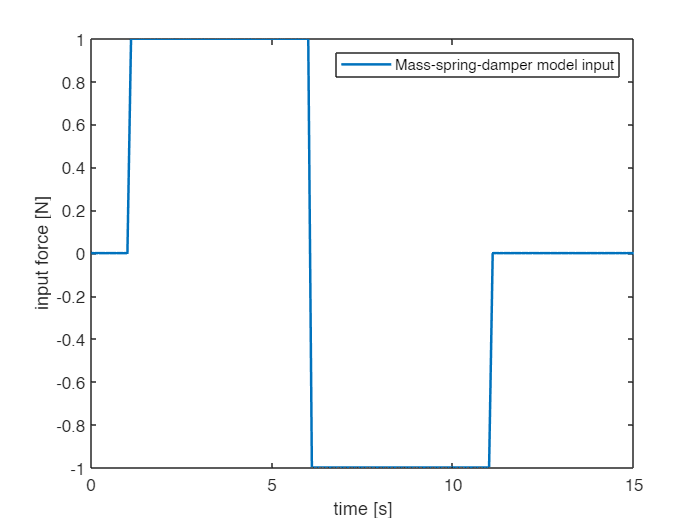

plot(timeVect, inputVect, 'LineWidth', 1.5);
xlabel('time [s]')
ylabel('input force [N]')
legend('Mass-spring-damper model input')


save('mdsInput.mat', 'timeVect', 'inputVect')

## Model params

DAMPER_CONST = 1;
MASS = 1;
SPRING_CONST = 1;

### Save

save('modelParams.mat', 'DAMPER_CONST', 'SPRING_CONST', 'MASS');